# Create a Table Using Entries and Rows

Create a table for a presentation by adding entries to rows and the rows to a table.

Create a presentation.

import mlreportgen.ppt.*
ppt = Presentation('myTableRowPresentation.pptx');
open(ppt);

Add a slide to the presentation.

add(ppt,'Title and Content');

Create a table.

table = Table();

Create the first table row.

tr1 = TableRow();
tr1.Style = [tr1.Style {Bold(true)}];

Create the table entries for the first row.

te1tr1 = TableEntry();
p = Paragraph('first entry');
p.FontColor = 'red';
append(te1tr1,p);
append(tr1,te1tr1);

te2tr1 = TableEntry();
append(te2tr1,'second entry');
append(tr1,te2tr1);

te3tr1 = TableEntry();
te3tr1.FontColor = 'green';
append(te3tr1,'third entry');
append(tr1,te3tr1);

Append the first table row to the table.

append(table,tr1);

Create the second table row, append the table entries to the row, and append the row to the table.

tr2 = TableRow();
te1tr2 = TableEntry();
te1tr2.FontColor ='red';
p = Paragraph('first entry');
append(te1tr2,p);
append(tr2,te1tr2);

te2tr2 = TableEntry();
append(te2tr2,'second entry');
append(tr2,te2tr2);

te3tr2 = TableEntry();
te3tr2.FontColor = 'green';
append(te3tr2,'third entry');
append(tr2,te3tr2);
append(table,tr2);

Add the table to the presentation.

contents = find(ppt,'Content');
replace(contents(1),table);
 

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the table in the generated presentation:

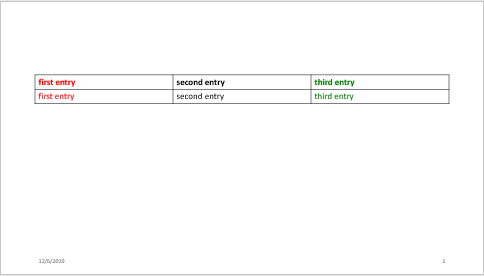

*Copyright 2019 The MathWorks, Inc.*